%Fmax = 5500; %最大筋力
Lopt = 0.055; %収縮要素の至適長
Lslack = 0.42; %弾性要素の自然長
mass = 70.0; %体重
Lcc0 = Lopt*0.7;

width = 0.888;
c = -1/width^2;
Fiso0 = c*(Lcc0/Lopt)^2 - 2*c*Lcc0/Lopt + c + 1;
q0 = 2*mass*98/(Fmax*Fiso0);

opts = odeset('RelTol', 1e-5, 'AbsTol', 1e-8, 'Event', 'dynEventFcn');

Ksec = zeros(31,1);
motiontime = zeros(31,1);
avePower = zeros(31,1);
posiPower = zeros(31,1);
negaPower = zeros(31,1);
deltaEsec = zeros(31,1);
maxF = zeros(31,1);
for k = 1:31
    Ksec(k) = (0.9+0.1*k)*10^5;
    Fmax = 5500*sqrt(0.9+0.1*k);
    ACTgene = ACT(k,:);
    Lsec0 = Lslack + 2*mass*9.8 / Ksec(k);
    [t,y] = ode45(@(t,y) dynamics(t,y,ACTgene,Fmax,Lopt,Lslack,Ksec(k),mass),...
        [0,0.5], [0;-1e-10;2*mass*9.8/(Fmax*Fiso0);Lcc0; Lsec0], opts);
    motiontime(k) = t(end);
    %deltaEsec(k) = Ksec(k)*(y(end,5)-Lslack)^2/2-Ksec(k)*(Lsec0-Lslack)^2/2;
    %netWork(k) = (2*mass*y(end,1)^2+deltaEsec(k));
    for l = 1:length(t)
        if y(l,3) < y(l+1,3)
            break;
        end
    end
    Pcc = -Ksec(k)*(y(:,5)-Lslack).*[0;diff(y(:,4))./diff(t)];
    %motiontime(k) = t(end)-t(l);
    %avePower(k) = sum(Pcc(l:end).*diff(t(l-1:end)))/motiontime(k);
    %posiPower(k) = sum(max(0,Pcc(l:end).*diff(t(l-1:end))))/motiontime(k);
    %negaPower(k) = sum(min(0,Pcc(l:end).*diff(t(l-1:end))))/motiontime(k);
    avePower(k) = sum(Pcc(2:end).*diff(t))/motiontime(k);
    posiPower(k) = sum(max(0,Pcc(2:end).*diff(t)))/motiontime(k);
    negaPower(k) = sum(min(0,Pcc(2:end).*diff(t)))/motiontime(k);
    maxF(k) = max(Ksec(k)*(y(:,5)-Lslack).^2);
end

%plot(Ksec,maxF)
figure;
yyaxis left
loglog(Ksec, avePower, 'o')
hold on
f = fit(Ksec, avePower, 'power2')

f =      General model Power2:
     f(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =  -2.511e+09  (-4.475e+09, -5.476e+08)
       b =      -1.592  (-1.66, -1.523)
       c =         107  (106.5, 107.4)

plot(f)
%plot(Ksec, posiPower)
%plot(Ksec, negaPower, '-.')
ylabel('power [W]')
yyaxis right
loglog(Ksec,motiontime,'o')
hold on
f = fit(Ksec, motiontime, 'power2')

f =      General model Power2:
     f(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =       547.5  (511.6, 583.4)
       b =     -0.7077  (-0.7138, -0.7016)
       c =      0.2159  (0.215, 0.2167)

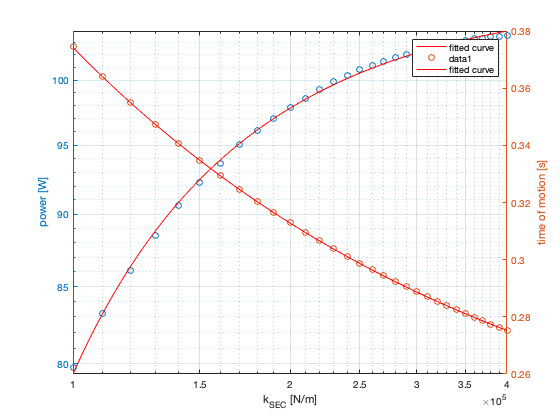

plot(f)
ylabel('time of motion [s]')
xlabel('k_{SEC} [N/m]')
%legend('total', 'positive', 'negative')
grid on